# Spectrogram Matrix

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

load ./data/monitoredfan.mat 

## Task 1

The displayed spectrogram is useful if you want to visually inspect the plot. But if you want to go further, you can get outputs from `spectrogram` to get the spectrogram in a matrix.

[s,f,t,ps] = spectrogram(monitoredfan,kaiser(2048,19),[],[],fs)

s = 1.0e+03 *

   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.0000 - 0.0

f = 1.0e+03 *

         0
    0.0012
    0.0023
    0.0035
    0.0047
    0.0059
    0.0070
    0.0082
    0.0094
    0.0105


t =     0.4267    0.8533    1.2800    1.7067    2.1333    2.5600    2.9867    3.4133    3.8400    4.2667    4.6933    5.1200    5.5467    5.9733    6.4000    6.8267    7.2533    7.6800    8.1067    8.5333    8.9600    9.3867    9.8133   10.2400   10.6667   11.0933   11.5200   11.9467   12.3733   12.8000   13.2267   13.6533   14.0800   14.5067   14.9333   15.3600   15.7867   16.2133   16.6400   17.0667   17.4933   17.9200   18.3467   18.7733   19.2000   19.6267   20.0533   20.4800   20.9067   21.3333


ps =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    

## Task 2

`s` and `ps` are both matrices of the same size. For both matrices, time increases across the columns and frequency increases down the rows, starting from zero. The time row vector `t` labels the columns and the frequency column vector `f` labels the rows.

How are `s` and `ps` different? Notice that `s` is complex and `ps` is real. `s` is the short-time Fourier transform, and `ps` is the power spectrum. If you want to display the power spectrum at one time instant, like you would with `periodogram`, you should use the power spectrum `ps`.

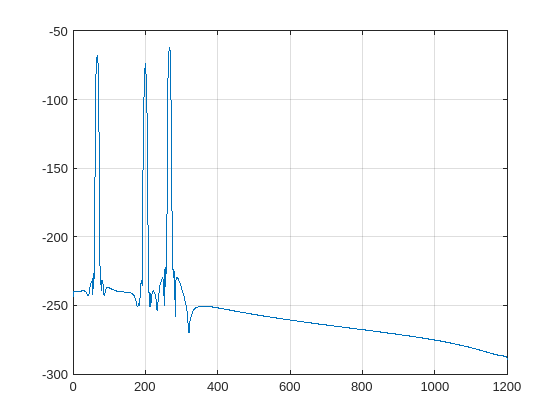

firstslice = ps(:,1);
plot(f,10*log10(firstslice))
grid on

## Task 3

The prominent frequencies in this plot are all harmonics of the fan's rotating frequency of 4000 rotations per minute (rpm) at 66.67 Hz. This means that the fan was working properly when the vibration signal began. If you'd like to confirm, try adding hovering your cursor on the plot to check that each peak is a multiple of 66.67 Hz.

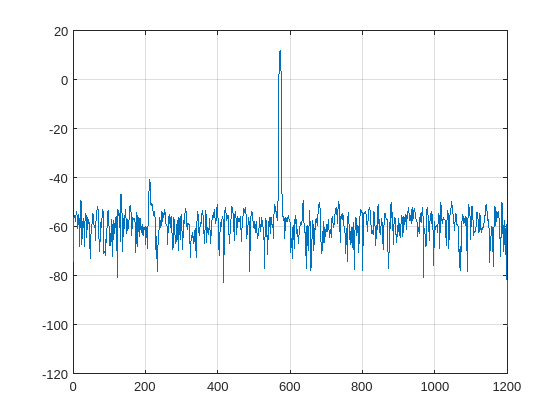

lastslice = ps(:,end);
plot(f,10*log10(lastslice))
grid on